# Fudamentals of Electromagnetics with Matlab

## Ch.1 - Matlab, Vectors and Phasors.

clear
clc


## Examples

% 1.1 

% Given the vectors, A=3ux and B=4uy to compute the sum C = A+B. Find the
% magnitude of C and the unit vector uc plot and label these vectors and 
% the unit vector ux and uy to illustrate the tip-to-tail addition method.

% input block
A = [3 0];
B = [0 4];
[A,B] = meshgrid (x,y);
quiver(x,y,u,v)

% compute
C = A+B % vector
M = norm (C) % magnitude
X = C/M % vector unit (v/norm(v)) 



## Problems



% 1.1.1 - Given two vectors A=3u_x+4u_y+5u_z, and B =-5u_x+4u_y-3u_z,
% find C=A+B and D=A-B
%In addition,carefully illustrate these vectors using MATLAB.

A = [3 4 5]; B = [-5 4 -3];% input block

C = A+B; %computing
D= A-B; %computing

C %output block

C =     -2     8     2


D %output block

D =      8     0     8



% 1.1.2. Using the vectors defined in Problem 1.1.1, evaluate A • B
% and A x B using MATLAB.

E = dot(A,B);
F = cross(A,B);

E % output block

E = -14

F % output block

F =    -32   -16    32


% 1.1.3 - Given two vectors A=ux+uy+uz,and B=2ux +4uy+6uz,find C=A+B and D=A- B.
% In addition, carefully illustrate these vectors using MATLAB.

% input block
A = [1 1 1];
B = [2 4 6];

% computing
C = A+B;
D = A-B;

%ouput block
C

C =      3     5     7


D

D =     -1    -3    -5



% 1.1.4 - Using the vectors defined in 1.1.3, evaluate A.B and AxB using MATLAB

% computing
E = dot (A,B);
F = cross (A,B);

%output
E

E = 12

F

F =      2    -4     2


% 1.1.5 - Using MATLAB, write a program to convert de-
% grees Celsius to degrees Fahrenheit. Plot the results.

% input data

tc = input ('insert here the value in Celsius: ');
conv = tc*(9/5)+32;
conv

conv = 93.2000

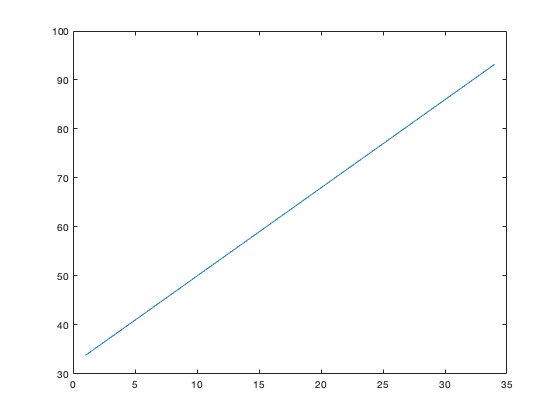


% compute
f=1:tc;
for i=1:tc
    x(i)=f(i)*(9/5)+32;
end
% output

plot (f,x);

% 1.1.6 - Using MATLAB, write a program to convert yardstick to a meterstick.
% Plot the results.

% input data
m = input ('insert here the value in Yards: ');
yd = m*1.0936;
yd

yd = 49.2120

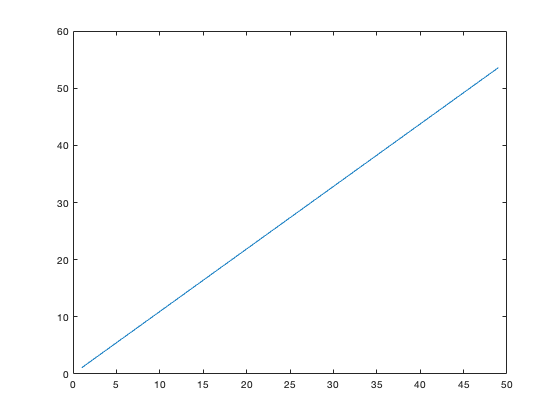

% compute
f=1:yd;
for i=1:yd
    c(i)=f(i)*1.0936;
end
% output
plot (f,c);

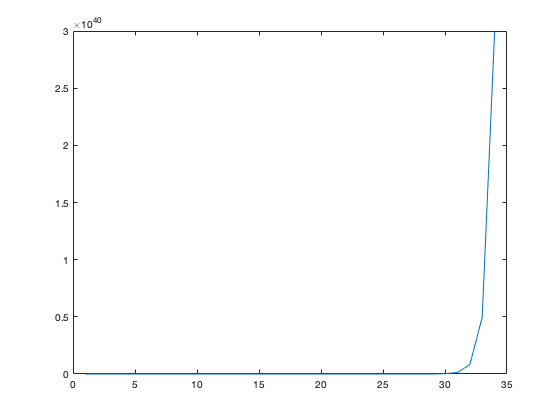


% 1.1.7 - Using MATLAB, ploty = e^(-x) on a linear and a
% semilog graph.

y = exp(x);
z = plot(y);

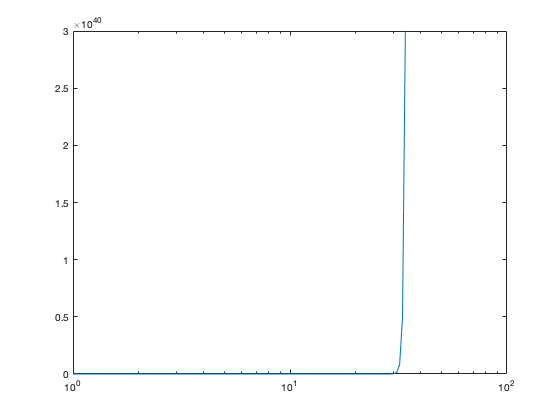

s = semilogx(y);